Caso Final 1: Sistema de Análisis de Datos de Ventas

El proyecto consiste en desarrollar un sistema de análisis de datos de ventas utilizando MATLAB. El sistema permitirá a los usuarios cargar conjuntos de datos de ventas, realizar análisis estadísticos básicos (total, promedio, máximo, mínimo), generar gráficos informativos y exportar los resultados. Esto proporcionará una herramienta útil para comprender mejor las tendencias de ventas y tomar decisiones comerciales fundamentadas.

CSV: [https://drive.google.com/file/d/1gMOCgNxsE12adP8GG0oIbwlmf4cHzP4g/view?usp=sharing](https://drive.google.com/file/d/1gMOCgNxsE12adP8GG0oIbwlmf4cHzP4g/view?usp=sharing)

Solución:

%Paso 1: Cargas la BD
salesData = readtable('datos_ventas.csv');


%Paso 2: Mostrar la información
disp('Información básica sobre los datos de ventas');

Información básica sobre los datos de ventas


disp(summary(salesData));

          Date: [1x1 struct]
    TotalSales: [1x1 struct]



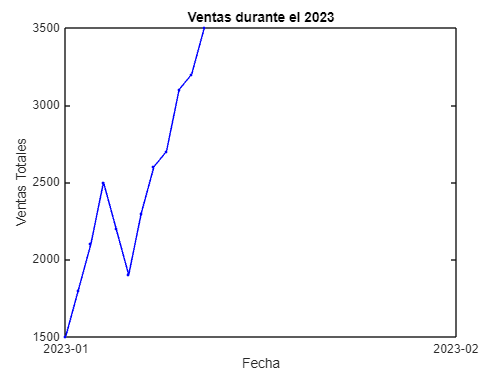


%Paso 3: Análisis estadístico básico
totalSales = sum(salesData.TotalSales);
averageSales = mean(salesData.TotalSales);
maxSales = max(salesData.TotalSales);
minSales = min(salesData.TotalSales);

%Paso 4: Gráficar las ventas a lo largo del 2023
figure;
plot(salesData.Date, salesData.TotalSales, 'b.-');
datetick('x', 'yyyy-mm');
xlabel('Fecha');
ylabel('Ventas Totales');
title('Ventas durante el 2023');


%Paso 5: Exportar resultados
exportSalesStats = [totalSales; averageSales; maxSales; minSales];
xlswrite('resultados_ventas.xlsx', exportSalesStats, 'Estadísticas de Ventas');

disp('Resultados exportados correctamente')

Resultados exportados correctamente
